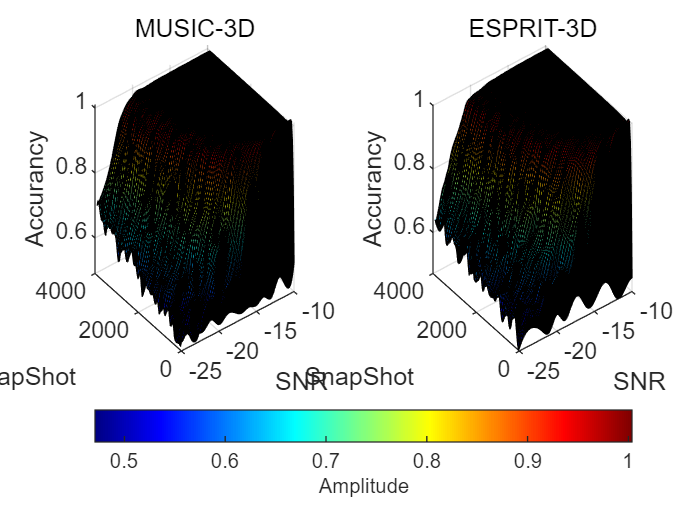

% 打开两个fig文件
fig1 = openfig('MUSIC-3D.fig');
fig2 = openfig('ESPRIT-3D.fig');

% 获取两个图的表面对象
surf1 = findobj(fig1, 'Type', 'surface');
surf2 = findobj(fig2, 'Type', 'surface');

% 获取数据
X1 = get(surf1, 'XData');
Y1 = get(surf1, 'YData');
Z1 = get(surf1, 'ZData');
X2 = get(surf2, 'XData');
Y2 = get(surf2, 'YData');
Z2 = get(surf2, 'ZData');

% 创建新图形窗口，设置一行两列布局
figure;
t = tiledlayout(1, 2, 'TileSpacing', 'compact');

% 绘制第一个子图 (MUSIC)
nexttile;
s1 = surf(X1, Y1, Z1);
% shading interp;
colormap(gca, 'jet'); % 设置 MUSIC 子图颜色为 jet
view(3);
title('MUSIC-3D');
xlabel('SNR'); ylabel('SnapShot'); zlabel('Accurancy');

% 绘制第二个子图 (ESPRIT)
nexttile;
s2 = surf(X2, Y2, Z2);
% shading interp;
colormap(gca, 'jet'); % 设置 ESPRIT 子图颜色为 jet
view(3);
title('ESPRIT-3D');
xlabel('SNR'); ylabel('SnapShot'); zlabel('Accurancy');

% 添加单一颜色条
cb = colorbar;
cb.Layout.Tile = 'south'; % 将颜色条放在底部
cb.Label.String = 'Amplitude';

% 调整图形布局
t.Padding = 'compact';

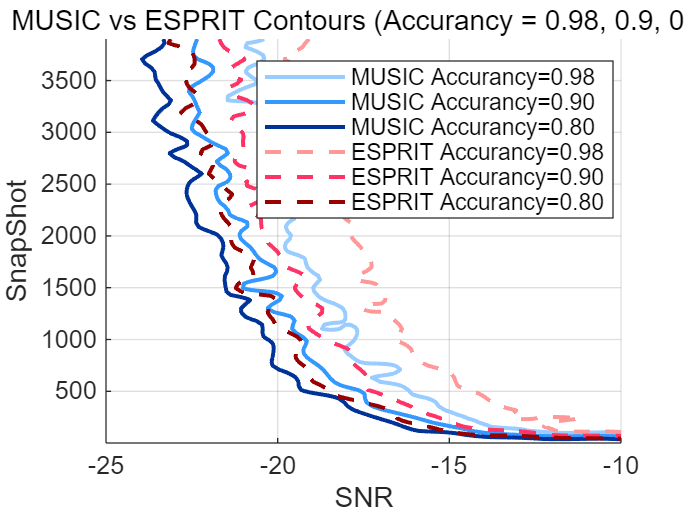


% 创建新图形用于等高线对比
figure;
hold on;

% 定义等高线级别
levels = [0.98, 0.9, 0.8];

% MUSIC等高线（浅蓝、天蓝、深蓝）
colors_music = [0.6 0.8 1; 0.2 0.6 1; 0 0.2 0.6];
for i = 1:length(levels)
    contour(X1, Y1, Z1, [levels(i) levels(i)], 'LineWidth', 1.5, ...
            'LineColor', colors_music(i, :), 'DisplayName', sprintf('MUSIC Accurancy=%.2f', levels(i)));
end

% ESPRIT等高线（浅红、玫红、深红）
colors_esprit = [1 0.6 0.6; 1 0.2 0.4; 0.6 0 0];
for i = 1:length(levels)
    contour(X2, Y2, Z2, [levels(i) levels(i)], 'LineWidth', 1.5, 'LineStyle', '--', ...
            'LineColor', colors_esprit(i, :), 'DisplayName', sprintf('ESPRIT Accurancy=%.2f', levels(i)));
end

% 设置图形属性
title('MUSIC vs ESPRIT Contours (Accurancy = 0.98, 0.9, 0.8)');
xlabel('SNR'); ylabel('SnapShot');
grid on;
legend('Location', 'best');
hold off;


% 关闭原始图形
close(fig1);
close(fig2);
